clear
clc
close all
% 弹体气动数据
V = 914.4;
a1 = 1.5;
a2 = -250;
a3 = 280;
a4 = 1.6;
a5 = 0.23;

kv = V/(57.3*9.8);

% 舵偏角闭环传递函数
A1 = a1+a4;
A2 = a2+a1*a4;

omega_n = 13.83;
omega_n1 = 22.14;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -8.3772

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -5.1445


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
    -5.145 s^2 - 15.95 s + 1274
  --------------------------------
  s^3 + 38.74 s^2 + 558.7 s + 4235
 
连续时间传递函数。
模型属性


step(G_deltabar_nye,1)
omega_n = 11.91;
omega_n1 = 29.85;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -8.3762

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -5.1439


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
    -5.144 s^2 - 15.95 s + 1274
  --------------------------------
  s^3 + 44.14 s^2 + 568.5 s + 4234
 
连续时间传递函数。
模型属性


hold on
step(G_deltabar_nye,1)

omega_n = 10.77;
omega_n1 = 36.55;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -8.3868

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -5.1504


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
     -5.15 s^2 - 15.97 s + 1275
  --------------------------------
  s^3 + 49.47 s^2 + 588.4 s + 4240
 
连续时间传递函数。
模型属性


hold on
step(G_deltabar_nye,1)

omega_n = 8.3;
omega_n1 = 44.62;
epsilon = 0.6;

N2 = omega_n1+2*epsilon*omega_n-A1;
N1 = omega_n^2+2*epsilon*omega_n*omega_n1-A2;
N0 = omega_n^2*omega_n1;

 
Kg = (omega_n1+2*epsilon*omega_n-A1+a5*omega_n1*omega_n^2/(a3*a4-a2*a5))/(-a3);
K_AC = omega_n1*omega_n^2/(Kg*kv);
KAC_Kg_kv =  -(omega_n^2*omega_n1)/(a3*a4-a2*a5)

KAC_Kg_kv = -6.0809

K_AC_Kg = KAC_Kg_kv/kv

K_AC_Kg = -3.7343


G_deltabar_nye = tf(K_AC_Kg.*[1 a1+a4 a2+a1*a4], [1 A1+N2 A2+N1 N0])

G_deltabar_nye =
 
    -3.734 s^2 - 11.58 s + 924.6
  --------------------------------
  s^3 + 54.58 s^2 + 513.3 s + 3074
 
连续时间传递函数。
模型属性


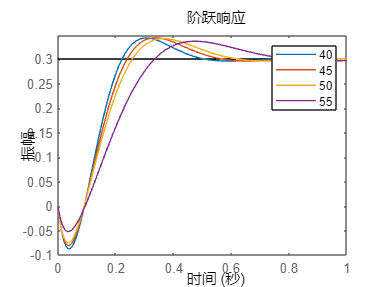

hold on
step(G_deltabar_nye,1)
legend('40','45','50','55')